First I'll have to load in the data, and I'll plot it. 

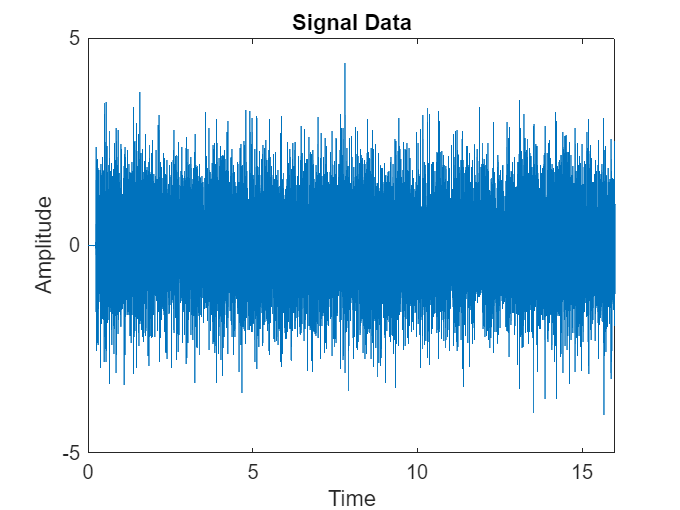

data = load("NOISE/testData.txt");
figure;
plot(data(:,1),data(:,2));
xlabel('Time');
ylabel('Amplitude');
title('Signal Data');

sf = 1/mean(diff(data(:,1)));

**FIXME:** What is the acronym PFD? Why not PSD?

Next I'm going to take a look at the total PFD, as well as the PFD before 5 seconds

**SDM: **I have reduced the segment length in the pwelch function. This increases the number of segments over which the averaging is done in Welch's method for PSD estimation and makes the PSD smoother

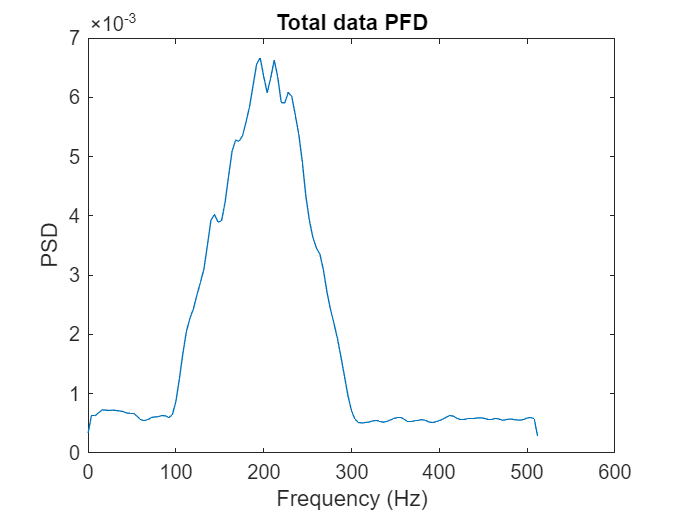

% first the total PFD
[ppx,f] = pwelch(data(:,2),128,[],[],sf);
figure; 
plot(f,ppx);
xlabel("Frequency (Hz)");
ylabel("PSD");
title("Total data PFD");

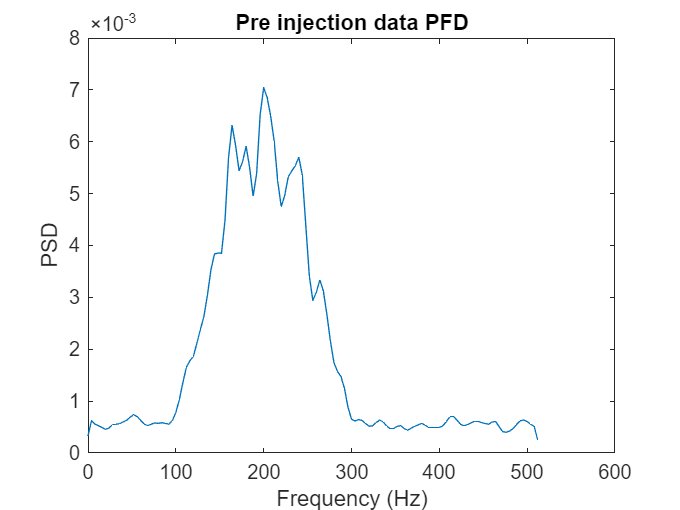


% PFD for t < 5s (noise PFD)
noisereg = data(:,1) < 5;
[nppx,nf] = pwelch(data(noisereg,2),128,[],[],sf);
figure;
plot(nf,nppx);
title("Pre injection data PFD");
xlabel("Frequency (Hz)");
ylabel("PSD");

There is a visible difference, though they are similar enough that the difference might only come from the lower number of datapoints. Either way, we will use the second PSD for our filtering. 

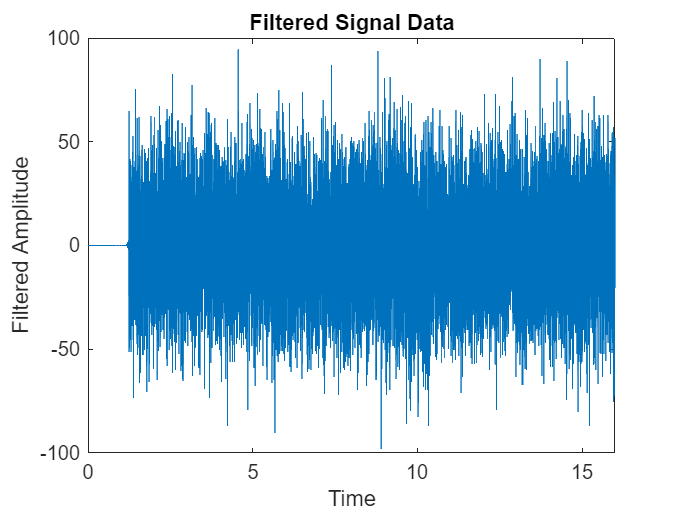

%b = fir2(2048 , nf/(sf/2), 1./nppx);
b = fir2(2048 , nf/(sf/2), 1./sqrt(nppx));
filtdata = fftfilt(b, data(:,2));
figure;
plot(data(:,1),filtdata);
xlabel("Time");
ylabel("Filtered Amplitude");
title("Filtered Signal Data");

Next I'm going to produce the PFD of the filtered data, to see how the whitened data looks. 

**SDM: **One should drop the filter startup transient before plotting the PSD of the filtered data. See the change below.

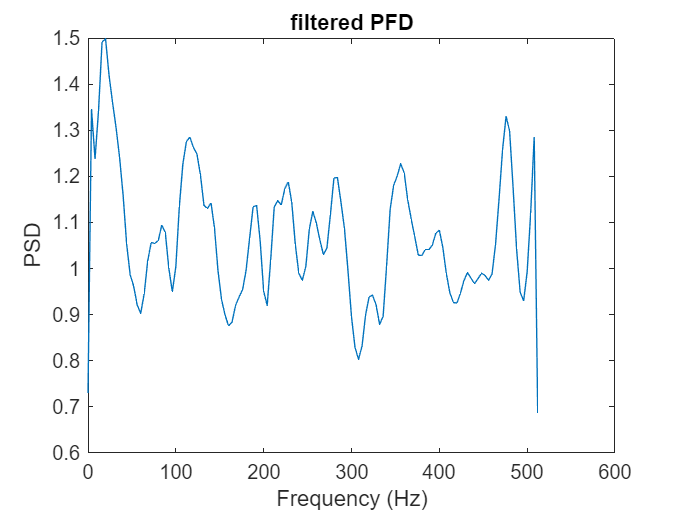

%SDM: Drop the filter startup transient (half the FIR filter order)
[fppx,ff] = pwelch(filtdata(1024:end),128,[],[],sf);
figure;
plot(ff,fppx);
title("filtered PFD");
xlabel("Frequency (Hz)");
ylabel("PSD");

Looking at this, we can see the signal PFD, and how it differes from the general PFD (which it does). 

**FIXME**: Missing the plotting of the spectrogram before and after whitening.